## 完整代码

clear; close all;
max1 = 3;
for ii=1:max1
% XmasTree
fig=figure('Units','normalized','Position',[.1,.05,.4,.8]);
ax=axes(fig);
hold(ax,'on');
ax.XTick=[];
ax.YTick=[];
ax.XColor='none';
ax.YColor='none';
ax.XLim=[0,600];
ax.YLim=[0,800];
ax.DataAspectRatio=[1 1 1];
ax.Color=[77 98 185]/255;        % 109,128,205]./255;

Col=[...
    65 105 225
    42  82  190
    106 90  205
    92  80  230
    77  128 230 ]/255;
cpl=Col(1,:);
cwl=Col(2,:);
cyl=Col(3,:);
czt=Col(4,:);
cswcl=Col(5,:);

colFurther=[240 34 75];  % 远山的颜色
colCloser=[219 43 60];   % 近山的颜色

colMoon=[245 184 29]./255;         % 236,235,253；银白
colStars=[237, 237, 195]/255;      % 1 1 1];
colTreeC = 1/255*...
[64 89 124
230 195 195
231,175,214];
colRibbon=[237,231,183]./255;       % [198,137,159]./255;
colPentagram=[247 245 142]./255;    % 249,211,107 [237,231,183]./255
colTrunk=cyl;
colSnow=[218,222,234]./255;
colMist=czt;           % 181,137,190





204 154 185

231,175,214

255,193,232

253, 227, 229

247, 230, 236

255, 228, 229

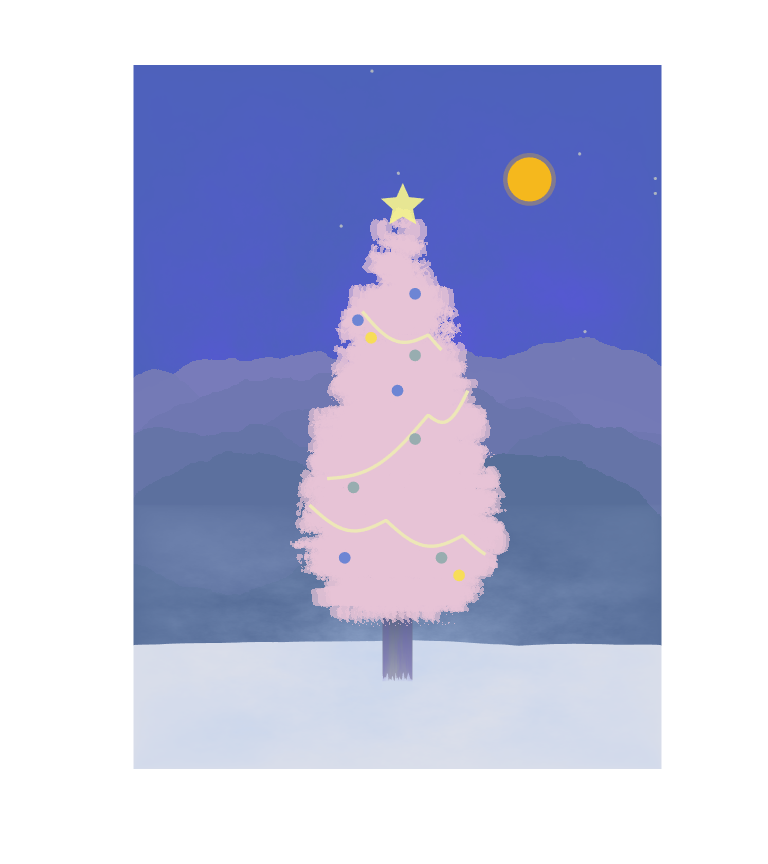

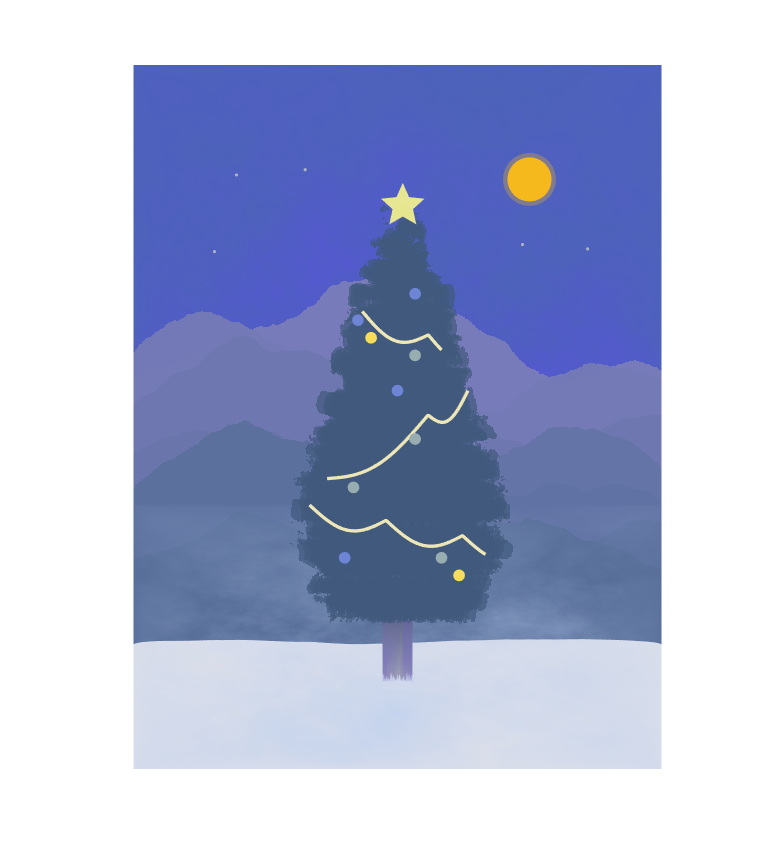

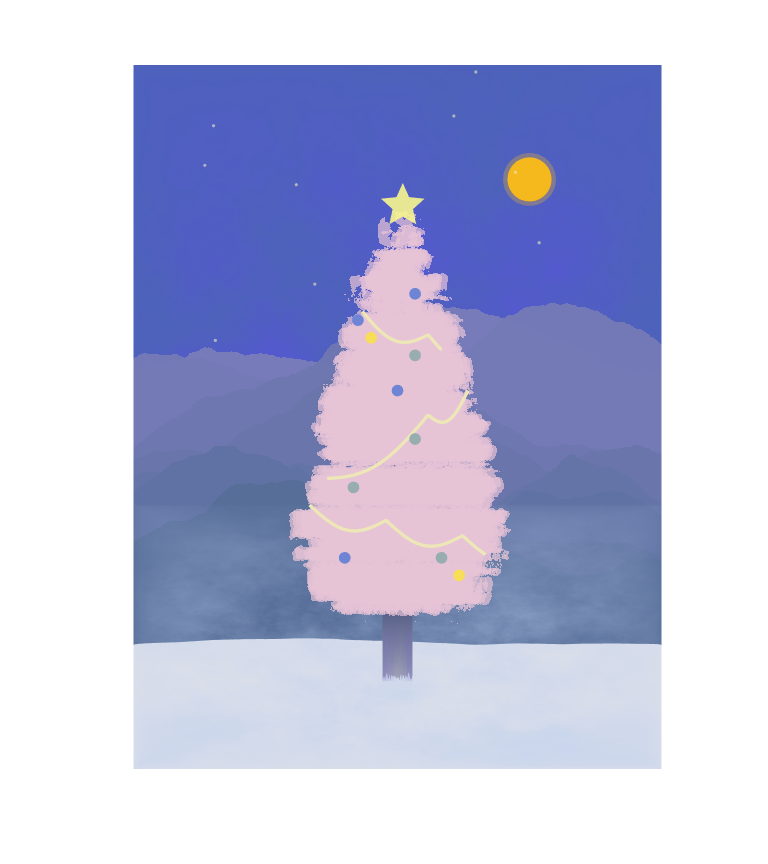

colTreeC = sort(colTreeC);
if mod(max1,ii)==0;jj=3;else jj=mod(max1,ii);end
colTree = colTreeC(jj,:);
% drawMist()      % 绘制雾气
% drawMandS()     % 绘制星星和月亮
% drawMountains() % 绘制山脉和雪地
% drawXMasTree()  % 绘制圣诞树


% =========================================================================
% 雾气绘制函数

%     function drawMist()
%         colMist=[181,137,190]./255;

        a=500;b=(.5:a)'/a;
        c=(-cos(b*2*pi)+1).^.2;
        f=b-.5;r=f'.^2+f.^2;
        
        % 二维柏林式噪声生成
        alp=abs(ifftn(exp(3i*rand(a))./r.^.8)).*(c*c');
        alp=alp./max(max(alp));
        
        CMesh=zeros([size(alp),3]);
        CMesh(:,:,1)=colMist(1);
        CMesh(:,:,2)=colMist(2);
        CMesh(:,:,3)=colMist(3);
        
        % 越向上、雾气越透明
        dy=(500:-1:1)./500.*.8+.2;
        image([0,600],[200,800],CMesh,'AlphaData',alp.*(dy'));
%     end
% -------------------------------------------------------------------------
% 星星月亮绘制函数
%     function drawMandS()

        % 绘制双层圆形当月亮
        t=0:pi/500:2*pi;
        fill(cos(t).*25+450,sin(t).*25+670,colMoon,'EdgeColor','none')
        fill(cos(t).*30+450,sin(t).*30+670,colMoon,'EdgeColor','none','FaceAlpha',.3)
        
        % 绘制散点当星星
        scatter(randi([0,600],[15,1]),randi([200,800],[15,1]),4,'filled',...
                'CData',colStars,'MarkerFaceAlpha',.6);
%     end
% -------------------------------------------------------------------------
% 山峰绘制函数
%     function drawMountains()

        % 绘制山峰- - - - - - - - - - - - - - - - - - - - - - - - - - - - -
        
        a=800;b=(.5:a)'/a;
        c=(-cos(b*2*pi)+1).^.2;
        f=b-.5;r=f'.^2+f.^2;
        % 8层山
        for i=1:8
            % 每次都生成一次二维柏林式噪声，并取其中一行的数据
            h=abs(ifftn(exp(5i*rand(a))./r.^1.05)).*(c*c').*10;
            nh=(8-i)*30+h(400,:)+180;
            hm=ceil(max(nh));
            CMesh=zeros([hm,800,3]);
            
            % 颜色矩阵构造，
            tcol=colFurther+(colCloser-colFurther)./8.*(i);
            tcol=hsv2rgb(tcol./[360,100,100]);
            CMesh(:,:,1)=tcol(1);
            CMesh(:,:,2)=tcol(2);
            CMesh(:,:,3)=tcol(3);
            
            % 用nan数值框出山的轮廓
            alp=ones(hm,800);
            alp((1:hm)'>nh)=nan;
            
            % 绘制山峰
            image([-50,650],[0,hm],CMesh,'AlphaData',alp.*0.98);        
        end
        
        
        % 画个雪地- - - - - - - - - - - - - - - - - - - - - - - - - - - - -
        nh=h(800,:);
        fill([linspace(0,600,length(nh)),600,0],[nh./1.5+140,0,0],colSnow,...
            'EdgeColor','none')
        
        % 雪地附近雾气- - - - - - - - - - - - - - - - - - - - - - - - - - -
        colMist=[155,172,198]./255.*1.2;
        a=500;b=(.5:a)'/a;
        c=(-cos(b*2*pi)+1).^.2;
        f=b-.5;r=f'.^2+f.^2;
        
        % 二维柏林式噪声生成
        alp=abs(ifftn(exp(3i*rand(a))./r.^.8)).*(c*c');
        alp=alp./max(max(alp));
        
        CMesh=zeros([size(alp),3]);
        CMesh(:,:,1)=colMist(1);
        CMesh(:,:,2)=colMist(2);
        CMesh(:,:,3)=colMist(3);
        
        % 越向上、雾气越透明
        dy=(500:-1:1)./500.*.6+.2;
        image([0,600],[0,300],CMesh,'AlphaData',alp.*(dy'));
%     end
% -------------------------------------------------------------------------
% 圣诞树绘制函数
%     function drawXMasTree()

        
        % 绘制树干- - - - - - - - - - - - - - - - - - - - - - - - - - - - -
        c=zeros(1,4,3);
        c(1,1:2,1)=163./255;c(1,1:2,2)=165./255;c(1,1:2,3)=183./255;
        c(1,3:4,1)=85./255 ;c(1,3:4,2)=95./255 ;c(1,3:4,3)=130./255;
        patch([283,317,317,283],[100,100,180,180],c,'FaceColor','interp','EdgeColor','none')
        fill([283:317,317,283],[100+rand(1,35).*10,90,90],[207,217,235]./255,'EdgeColor','none')
        
        % 绘制树干粗糙花纹- - - - - - - - - - - - - - - - - - - - - - - - -
        a=400;b=(.5:a)'/a;
        c=(-cos(b*2*pi)+1).^.2;
        f=b-.5;r=f'.^2+f.^2;
        
        alp=abs(ifftn(exp(3i*rand(a))./r.^.8)).*(c*c');
        alp=alp./max(max(alp));
        alp=alp(1:100,:);
        
%         colTrunk=[160,162,177]./255;
        CMesh=zeros([size(alp),3]);
        CMesh(:,:,1)=colTrunk(1);
        CMesh(:,:,2)=colTrunk(2);
        CMesh(:,:,3)=colTrunk(3);
        
        dy=(100:-1:1)./100.*.8+.2;
        image([283,317],[100,180],CMesh,'AlphaData',alp.*(dy'));
        
        % 绘制树叶- - - - - - - - - - - - - - - - - - - - - - - - - - - - -
%         colTree=[64,88,124]./255;
        a=100;b=(.5:a)'/a;
        c=(-cos(b*2*pi)+1).^.2;
        f=b-.5;r=f'.^2+f.^2;
            
        CMesh=zeros([a,a,3]);
        CMesh(:,:,1)=colTree(1);
        CMesh(:,:,2)=colTree(2);
        CMesh(:,:,3)=colTree(3);
        
        jList=[1,2,3,5,6,8,10,12,14,16,16,18,18,20,20,24,24,26,26,28,...
               28,30,30,32,32,32,32,34,32,32,30,26,26,20];
        for i=1:34
            % 二维柏林式噪声生成
            alp=abs(ifftn(exp(7i*rand(a))./r.^.9)).*(c*c');
            alp=alp./max(max(alp));
            alp(alp<.5)=0;
            alp(alp>=.5)=.7;
            for j=(1:jList(i))-jList(i)/2
                image([270,330]+j*6+(rand(1)-.5).*6,...
                      [200,260]+400-i*13+(rand(1)-.5).*3,CMesh,'AlphaData',alp);
            end
        end
        
        % 绘制五角星- - - - - - - - - - - - - - - - - - - - - - - - - - - - 
        t=linspace(pi/2,2*pi+pi/2,11);
        l=ones(1,11);l(2:2:11)=.47;
        fill(cos(t).*26.*l+306,sin(t).*26.*l+640,colPentagram,...
            'EdgeColor','none','FaceAlpha',.9)
        
        % 绘制其他装饰物- - - - - - - - - - - - - - - - - - - - - - - - - -
        % 绘制彩带
        siny=-abs(sin(linspace(0,2.3*pi,100)))-linspace(0,2,100);
        plot(linspace(200,400,100),siny.*20+300,'Color',colRibbon,'LineWidth',2)
        siny=-abs(sin([linspace(0,pi,100),linspace(0,pi,40)]))-linspace(0,-5,140);
        plot(linspace(220,380,140),siny.*20+330,'Color',colRibbon,'LineWidth',2)
        siny=-abs(sin(linspace(0,1.2*pi,100)))-linspace(0,1.6,100);
        plot(linspace(260,350,100),siny.*20+520,'Color',colRibbon,'LineWidth',2)
        % 绘制装饰圆球
        scatter([-50,20,20,50]+300,[-80,-25,70,-160]+400,50,'filled','CData',[152,173,176]./255);
        scatter([-45,0,20,-60]+300,[110,30,140,-160]+400,50,'filled','CData',[109,133,212]./255);
        scatter([-30,70]+300,[90,-180]+400,50,'filled','CData',[247 221 88]./255);% 203,202,181
%     end
end
